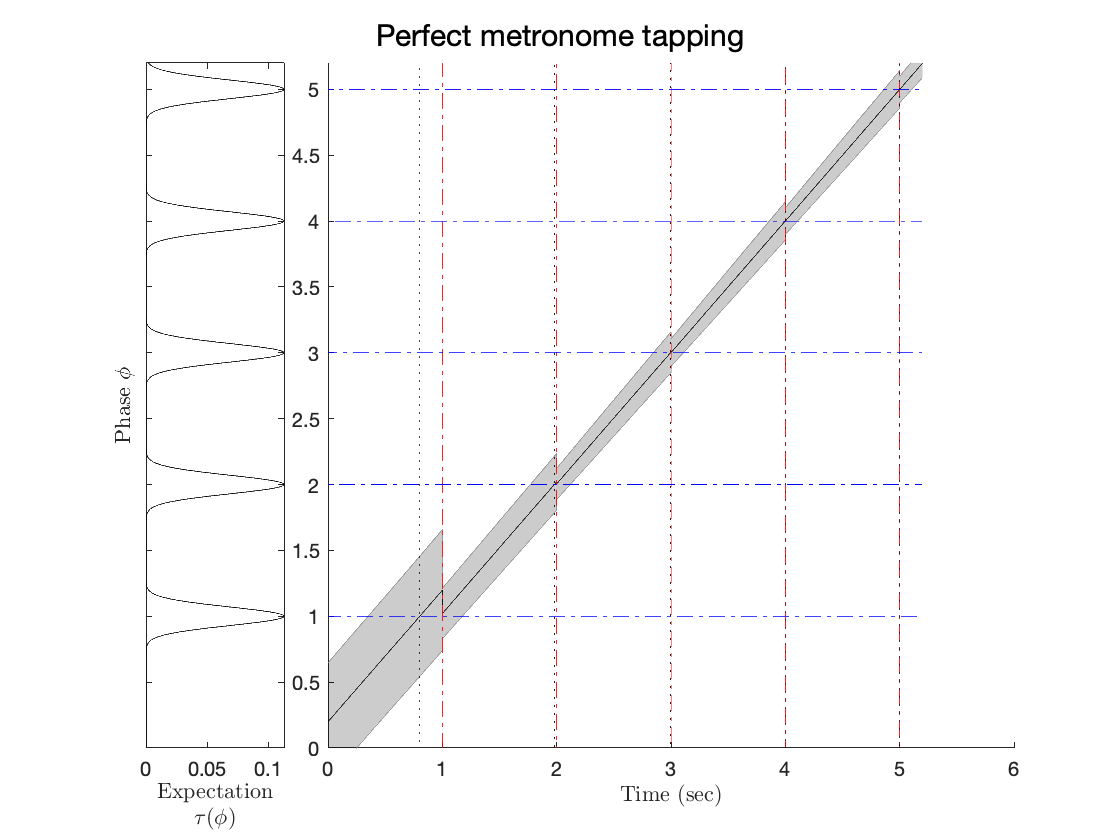

% (C) Jonathan Cannon, MIT, 2020

n_events = 5;
event_times = 1:n_events;

params = PIPPET_params(...
    'tau_unit', 0.02,...
    'means_unit', [1],...
    'variance_unit', [.005],...
    'event_times',[.25, .5,.75, 1],...
    'tau_unit', [.02],...
    'tau_0', 0,...
    'expected_cycles', n_events,...
    'expected_period', 1,...
    'V_0', .05,...
    'phibar_0', .2,...
    'event_times', event_times, ...
    'tapping', true,...
    'title', 'Perfect metronome tapping');
[phibar_list, V_list] = run_PIPPET(params);

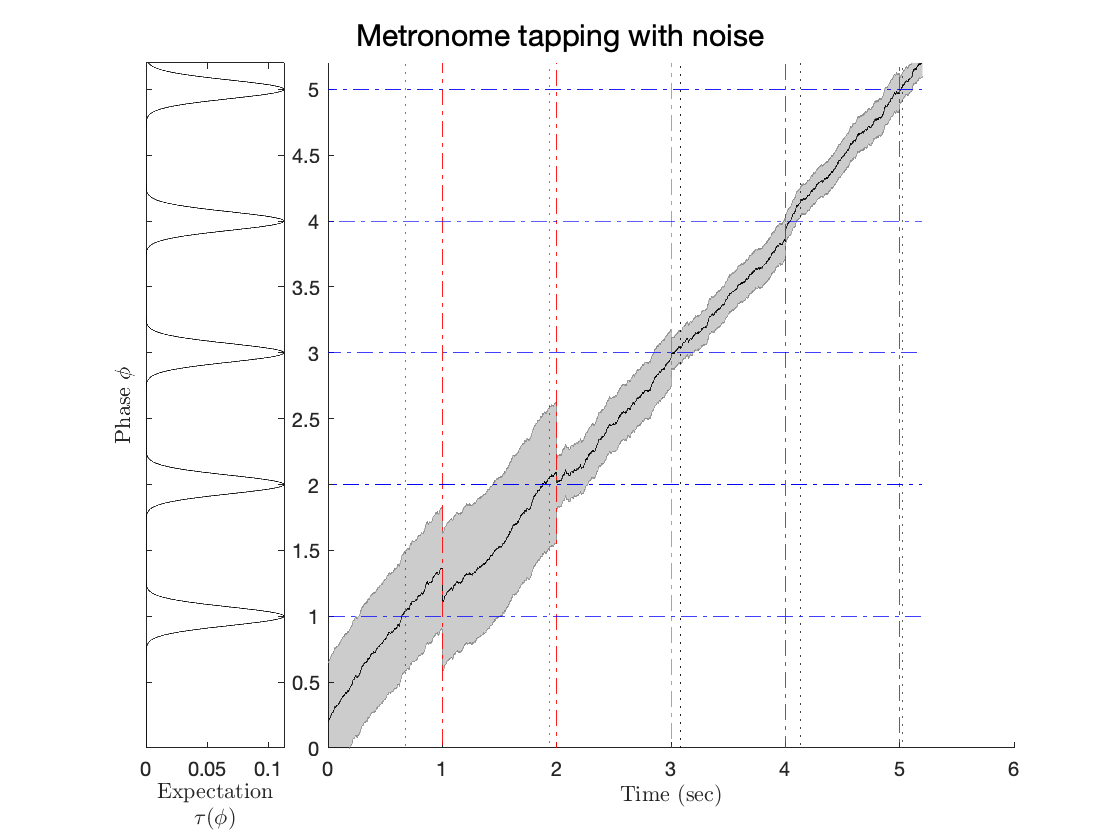



params2 = PIPPET_params(...
    'tau_unit', 0.02,...
    'means_unit', [1],...
    'variance_unit', [.005],...
    'event_times',[.25, .5,.75, 1],...
    'tau_unit', [.02],...
    'tau_0', 0,...
    'expected_cycles', n_events,...
    'expected_period', 1,...
    'V_0', .05,...
    'phibar_0', .2,...
    'eta_phi', .1,...
    'event_times', event_times, ...
    'tapping', true,...
    'title', 'Metronome tapping with noise');
[phibar_list, V_list] = run_PIPPET(params2);

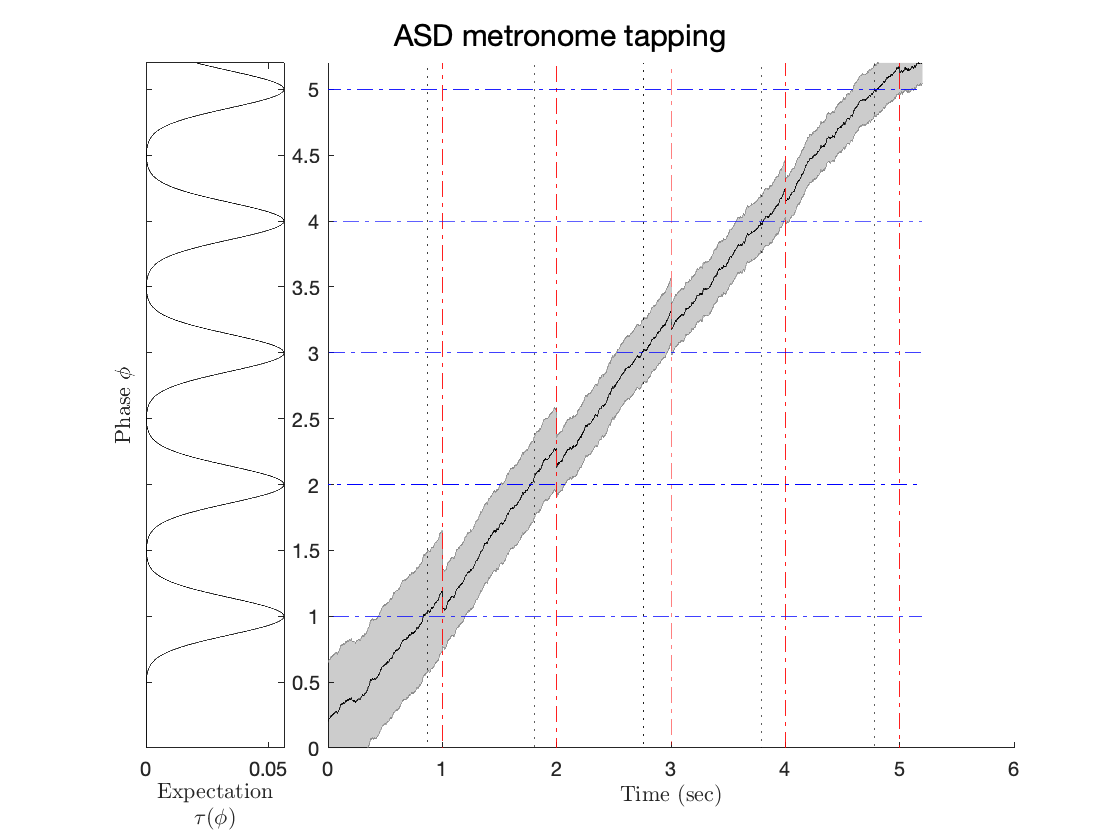

phibar_list =     0.2000    0.2049    0.2079    0.2130    0.2101    0.2121    0.2148    0.2154    0.2180    0.2211    0.2231    0.2282    0.2255    0.2273    0.2242    0.2244    0.2248    0.2255    0.2248    0.2285    0.2302    0.2363    0.2377    0.2406    0.2430    0.2450    0.2462    0.2481    0.2413    0.2399    0.2444    0.2417    0.2471    0.2444    0.2494    0.2500    0.2464    0.2478    0.2485    0.2531    0.2553    0.2579    0.2564    0.2517    0.2556    0.2574    0.2555    0.2605    0.2568    0.2595


V_list =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501    0.0501



params3 = PIPPET_params(...
    'tau_unit', 0.02,...
    'means_unit', [1],...
    'variance_unit', [.02],...
    'event_times',[.25, .5,.75, 1],...
    'tau_unit', [.02],...
    'tau_0', 0,...
    'expected_cycles', n_events,...
    'expected_period', 1,...
    'V_0', .05,...
    'phibar_0', .2,...
    'eta_phi', .1,...
    'event_times', event_times, ...
    'tapping', true,...
    'title', 'ASD metronome tapping');
[phibar_list, V_list] = run_PIPPET(params3)



%Tapping autocorr

n_events = 1000;
tap_thresh = .7;
event_times = 1:n_events;

expectation_variance_list = [.005, .02];
condition_list = {'NT', 'ASD'};

async_list = {[],[]};
AC_list = {[],[]};
alpha_list = [0,0];

for condition = 1:length(expectation_variance_list)
    params = PIPPET_params(...
        'means_unit', [1],...
        'variance_unit', [expectation_variance_list(condition)],...
        'tau_unit', [.02],...
        'tau_0', 0,...
        'expected_cycles', n_events,...
        'expected_period', 1,...
        'event_times', event_times,...
        'display', false,...
        'eta_phi', .05,...
        'tapping', true,...
        'title', 'Tap along');
    [phibar_list, V_list, tap_times] = run_PIPPET(params);

    async =  tap_times(1:length(event_times)) - event_times;
    async_list{condition} = async;
    AC_list{condition} = autocorr(async);
    
end

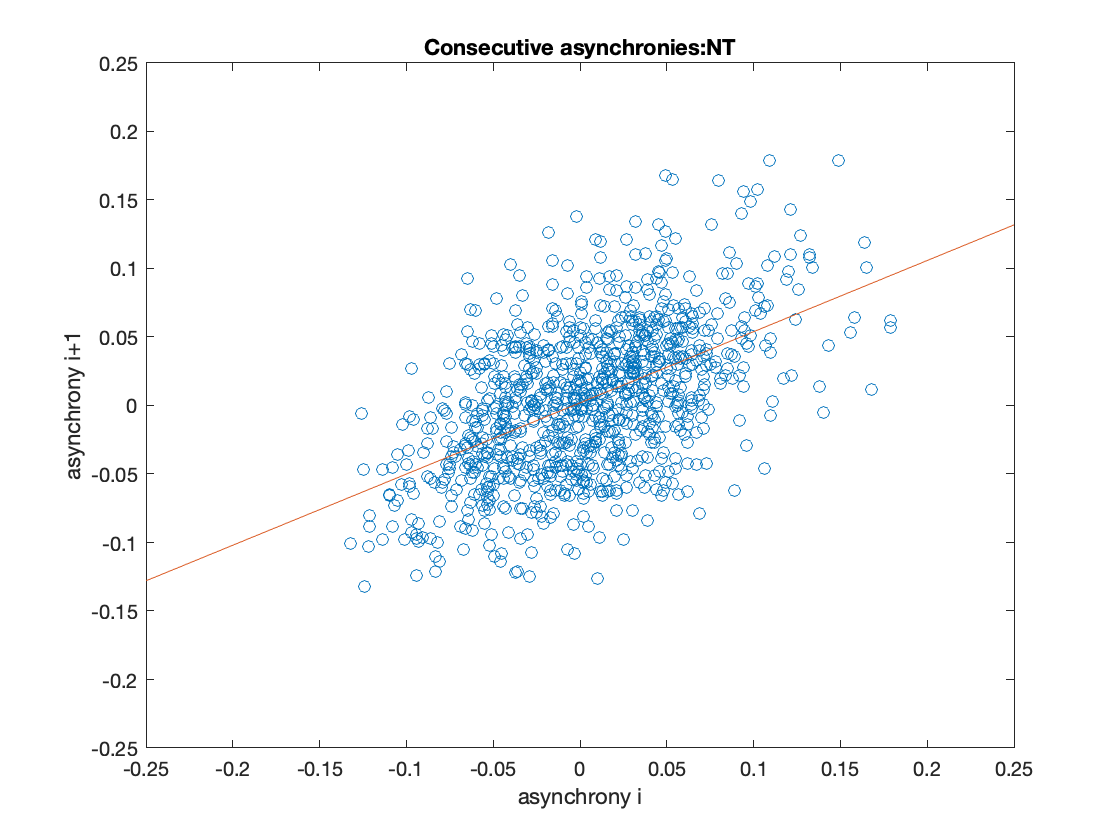

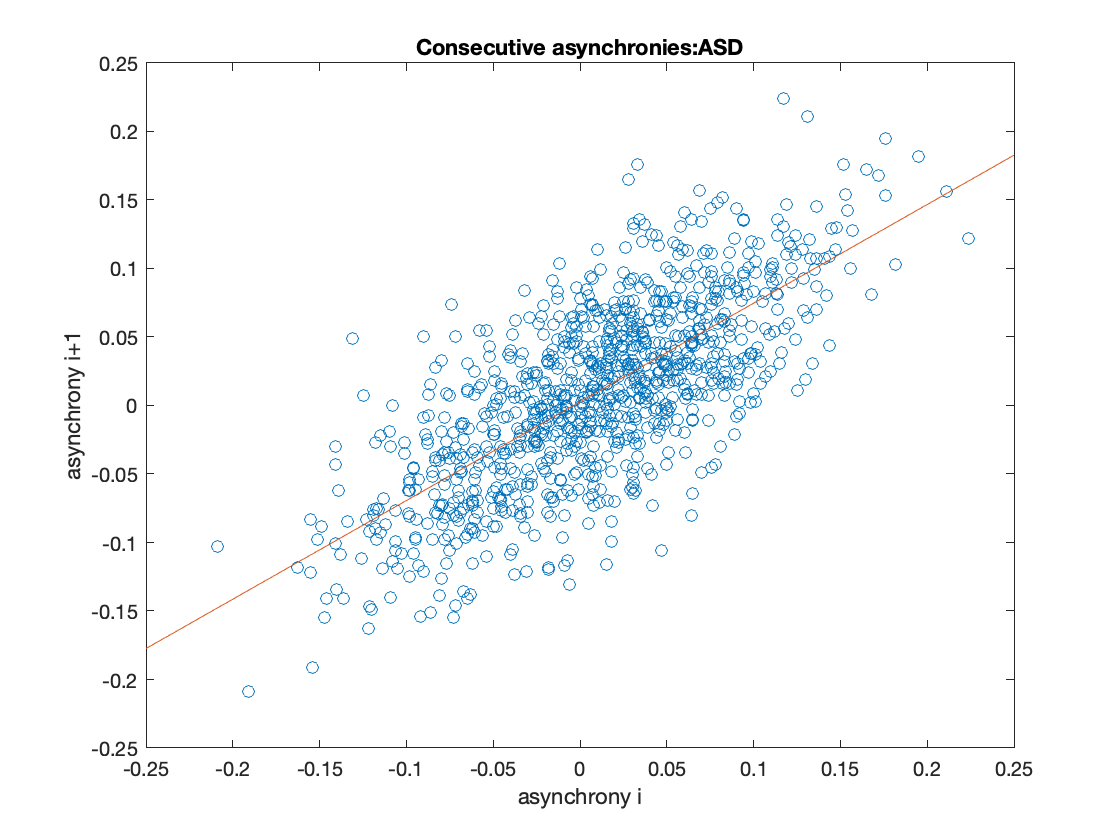



for condition = 1:length(condition_list)
    figure()
    P = polyfit(async_list{condition}(1:end-1),async_list{condition}(2:end),1);
    plot(async_list{condition}(1:end-1), async_list{condition}(2:end), 'o')
    hold on
    plot([-.25, .25], P(1)*[-.25, .25]+P(2));
    title(strcat('Consecutive asynchronies: ', condition_list{condition}));
    xlim([-.25, .25])
    ylim([-.25, .25])
    xlabel('asynchrony i')
    ylabel('asynchrony i+1')
end

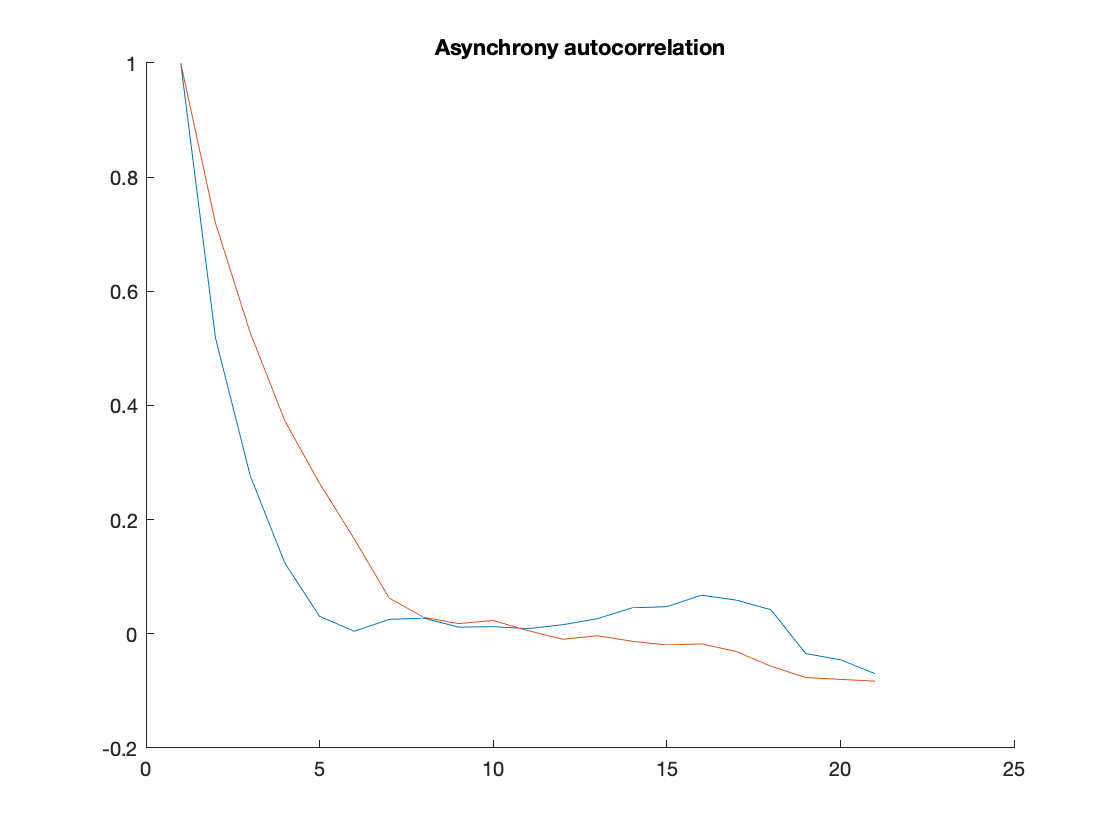


figure()
hold on
for condition = 1:length(expectation_variance_list)
    
    plot(AC_list{condition})
end
title('Asynchrony autocorrelation')